clear;
global x0
B = [0; 0]; C = [1 0; 0 1]; D = [0; 0];

Układ 1

Węzeł stabilny

$$V = \left(\begin{array}{c} Y_{2}\\ -2\,{Y_{1}}^{3}-\frac{3\,Y_{1}}{10}-3\,Y_{2} \end{array}\right)$$

V = function_handle with value:
    @(t,Y)[Y(2);Y(1).^3.*-2.0-Y(1).*(3.0./1.0e+1)-Y(2).*3.0]


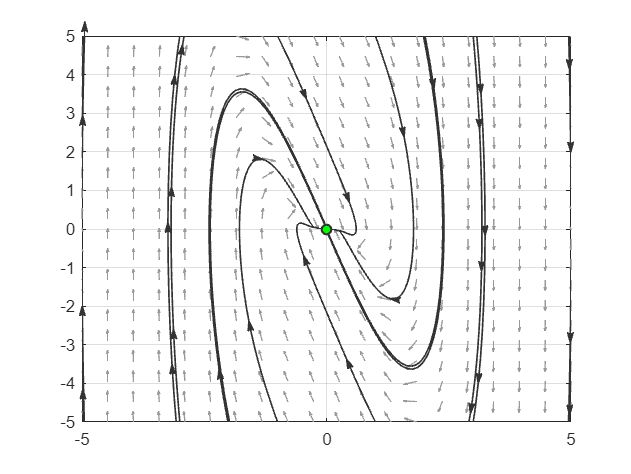

eigs =    -2.8964
   -0.1036


A =          0    1.0000
   -0.3000   -3.0000


bal_point =      0     0


b = 3;
c = 0.3;
d = 2;

syms y(t)
% Rownanie drugiego rzedu opisujace uklad
eqn = diff(y,2) + b * diff(y, 1) + c * y + d * y^3 == 0;
% Macierze ukladu zlinearozywanego w punktach rownowagi i ich wartosci
% wlasne
[eigs, A, bal_point] = lapunov_stab(eqn)

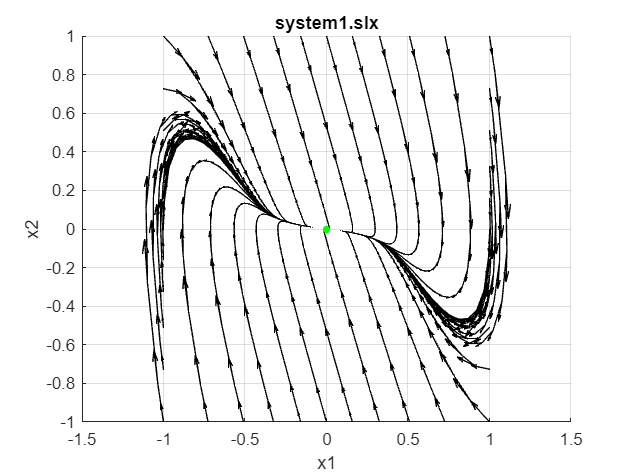


% Portret fazowy
fig = draw_phase("system1.slx");
hold on;
plot(bal_point(:, 1), bal_point(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
hold off;

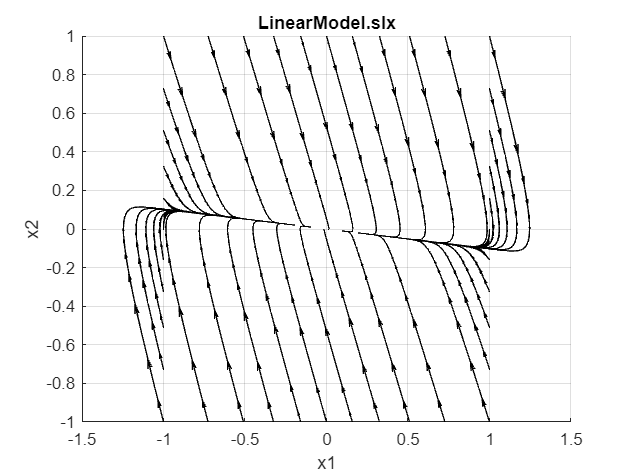

%saveas(fig ,"wykresy/1system1.jpg");

% Portret fazowy zlinearyzowanego przyblizenia
fig = draw_phase("LinearModel.slx");

%plot_pp_by_A(A);
%saveas(fig ,"wykresy/lin_system1.jpg");

Ognisko stabilne

$$V = \left(\begin{array}{c} Y_{2}\\ -2\,{Y_{1}}^{3}-\frac{3\,Y_{1}}{2}-\frac{Y_{2}}{2} \end{array}\right)$$

V = function_handle with value:
    @(t,Y)[Y(2);Y(1).^3.*-2.0-Y(1).*(3.0./2.0)-Y(2)./2.0]


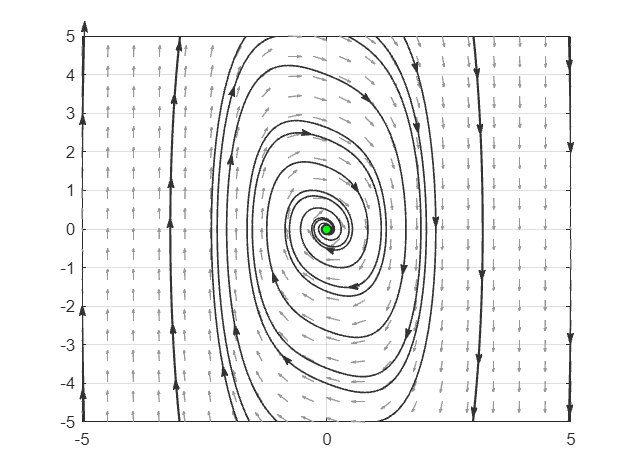

eigs =   -0.2500 - 1.1990i
  -0.2500 + 1.1990i


A =          0    1.0000
   -1.5000   -0.5000


bal_point =      0     0


b = 0.5;
c = 1.5;
d = 2;

syms y(t)
% Rownanie drugiego rzedu opisujace uklad
eqn = diff(y,2) + b * diff(y, 1) + c * y + d * y^3 == 0;
% Macierze ukladu zlinearozywanego w punktach rownowagi i ich wartosci
% wlasne
[eigs, A, bal_point] = lapunov_stab(eqn)

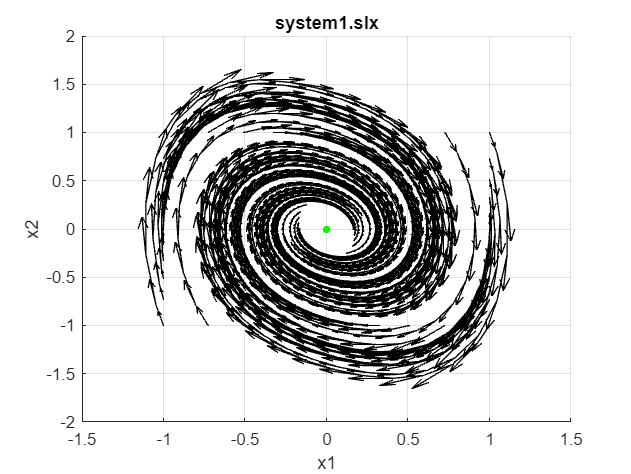


% Portret fazowy
fig = draw_phase("system1.slx");
hold on;
plot(bal_point(:, 1), bal_point(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
hold off;

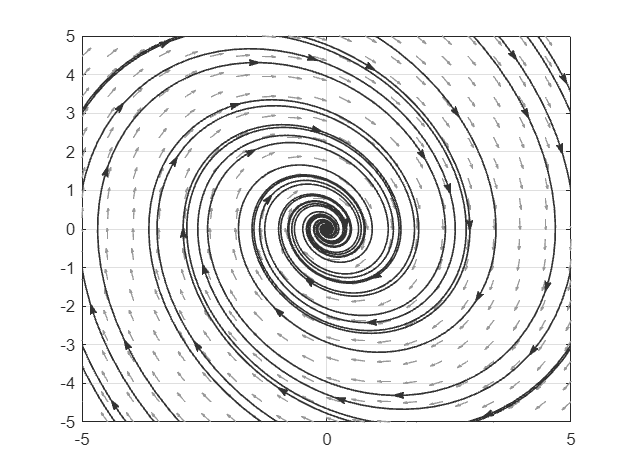

%saveas(fig ,"wykresy/system1.jpg");

% Portret fazowy zlinearyzowanego przyblizenia
%fig = draw_phase("LinearModel.slx");
plot_pp_by_A(A);

%saveas(fig ,"wykresy/lin_system1.jpg");

Spręzyna miękka

$$V = \left(\begin{array}{c} Y_{2}\\ 2\,{Y_{1}}^{3}-\frac{3\,Y_{1}}{2}-\frac{Y_{2}}{2} \end{array}\right)$$

V = function_handle with value:
    @(t,Y)[Y(2);Y(1).^3.*2.0-Y(1).*(3.0./2.0)-Y(2)./2.0]


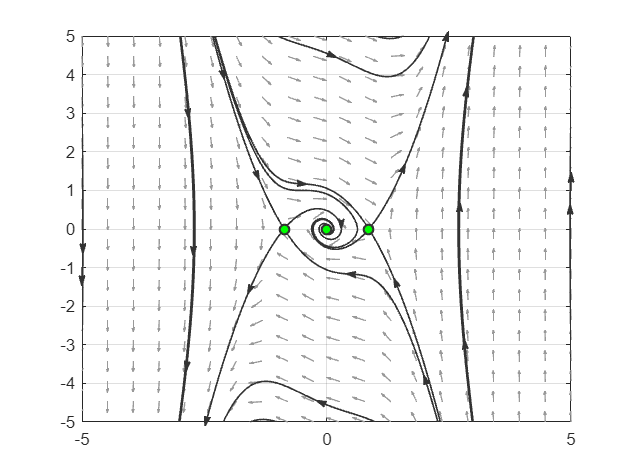

eigs =   -0.2500 - 1.1990i  -2.0000 + 0.0000i  -2.0000 + 0.0000i
  -0.2500 + 1.1990i   1.5000 + 0.0000i   1.5000 + 0.0000i


Am = Am(:,:,1) =

         0    1.0000
   -1.5000   -0.5000


Am(:,:,2) =

         0    1.0000
    3.0000   -0.5000


Am(:,:,3) =

         0    1.0000
    3.0000   -0.5000


bal_points =          0         0
   -0.8660         0
    0.8660         0


b = 0.5;
c = 1.5;
d = -2;

syms y(t)
% Rownanie drugiego rzedu opisujace uklad
eqn = diff(y,2) + b * diff(y, 1) + c * y + d * y^3 == 0;
% Macierze ukladu zlinearozywanego w punktach rownowagi i ich wartosci
% wlasne
[eigs, Am, bal_points] = lapunov_stab(eqn)

bal_point =      0     0


A =          0    1.0000
   -1.5000   -0.5000


point_eigs =   -0.2500 - 1.1990i
  -0.2500 + 1.1990i


bal_point =    -0.8660         0


A =          0    1.0000
    3.0000   -0.5000


point_eigs =    -2.0000
    1.5000


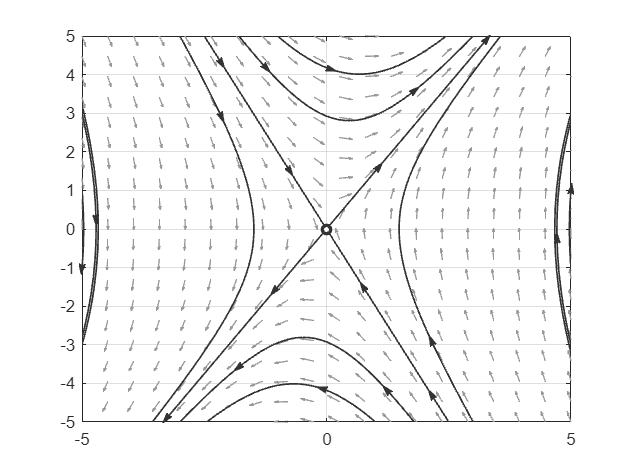

bal_point =     0.8660         0


A =          0    1.0000
    3.0000   -0.5000


point_eigs =    -2.0000
    1.5000



% Portret fazowy
%fig = draw_phase("system1.slx");
%hold on;
%plot(bal_points(:, 1), bal_points(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
%hold off;
%saveas(fig ,"wykresy/2system1.jpg");

% Portret fazowy zlinearyzowanego przyblizenia
for i = 1 : size(Am,3)
    bal_point = bal_points(i,:)
    A = Am(:,:,i)
    point_eigs = eigs(:,i)
    plot_pp_by_A(A)
end

Wahadło

$$V = \left(\begin{array}{c} Y_{2}\\ -\frac{981\,\sin\left(Y_{1}\right)}{100}-\frac{9\,Y_{2}}{5} \end{array}\right)$$

$$bal\_y1 = \pi \,k$$

$$param = k$$

$$cond = k\in \mathbb{Z}$$

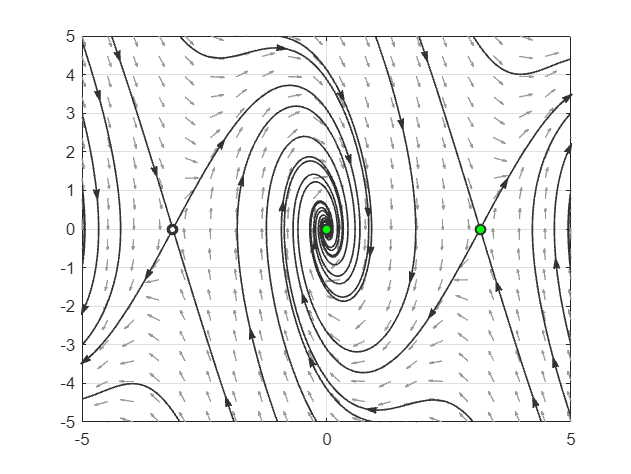

g = 9.81;
m = 0.5;
l = 1;
c = 0.9;

eqn = diff(y,2) + (g/l) * sin(y) + (c / (l*m)) * diff(y,1) == 0;
[all_eigs, Am, bal_points] = lapunov_stab2(eqn);

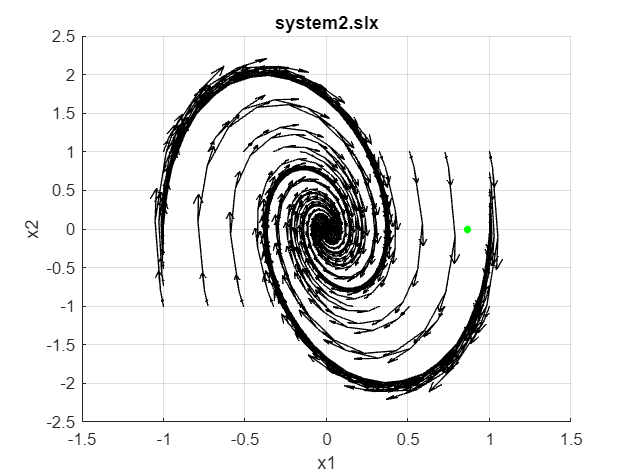


fig = draw_phase("system2.slx");
hold on;
plot(bal_point(:, 1), bal_point(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
hold off;

bal_point =      0     0


A =          0    1.0000
   -9.8100   -1.8000


point_eigs =   -0.9000 - 3.0000i
  -0.9000 + 3.0000i


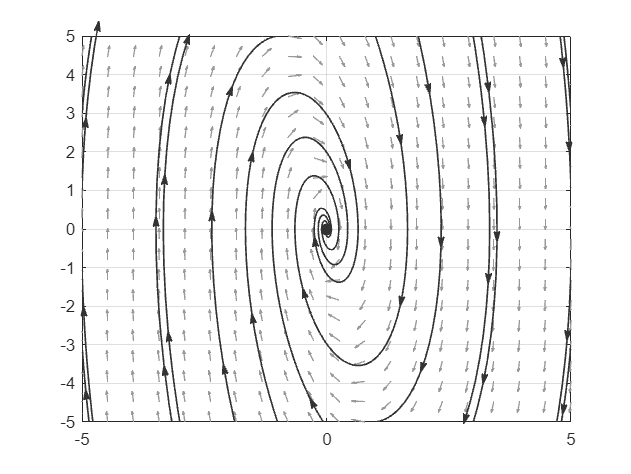

bal_point =     3.1416         0


A =          0    1.0000
    9.8100   -1.8000


point_eigs =    -4.1588
    2.3588


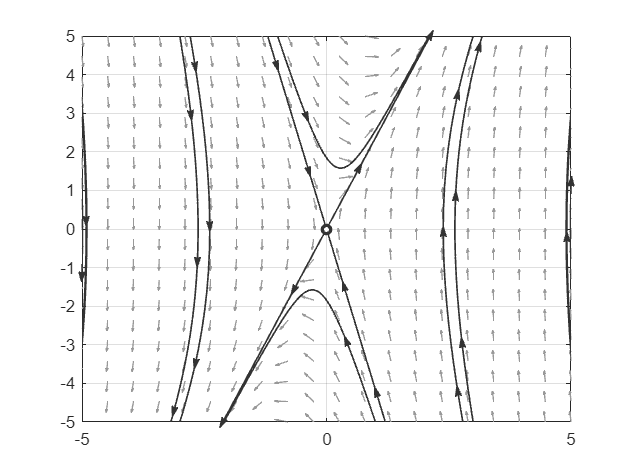

%saveas(fig ,"wykresy/system2.jpg");

for i = 1 : size(Am,3)
    bal_point = bal_points(i,:)
    A = Am(:,:,i)
    point_eigs = all_eigs(:,i)
    plot_pp_by_A(A)
    %fig = draw_phase("LinearModel.slx");
    %saveas(fig ,"wykresy/lin_system2" + string(i) + ".jpg");
end

Węzeł

$$V = \left(\begin{array}{c} Y_{2}\\ -\frac{981\,\sin\left(Y_{1}\right)}{50}-12\,Y_{2} \end{array}\right)$$

$$bal\_y1 = \pi \,k$$

$$param = k$$

$$cond = k\in \mathbb{Z}$$

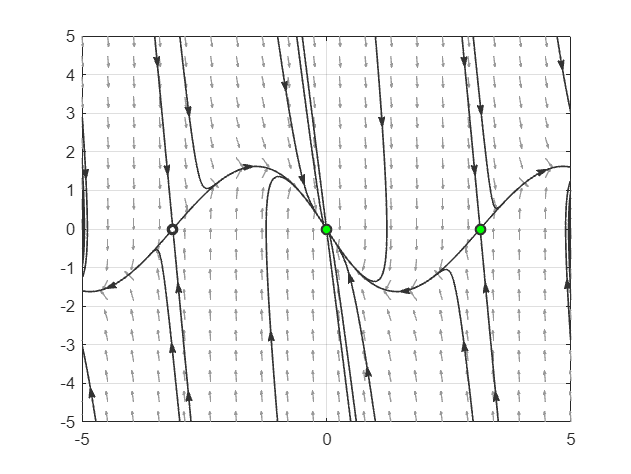

g = 9.81;
m = 0.5;
l = 0.5;
c = 3;

eqn = diff(y,2) + (g/l) * sin(y) + (c / (l*m)) * diff(y,1) == 0;
[all_eigs, Am, bal_points] = lapunov_stab2(eqn);

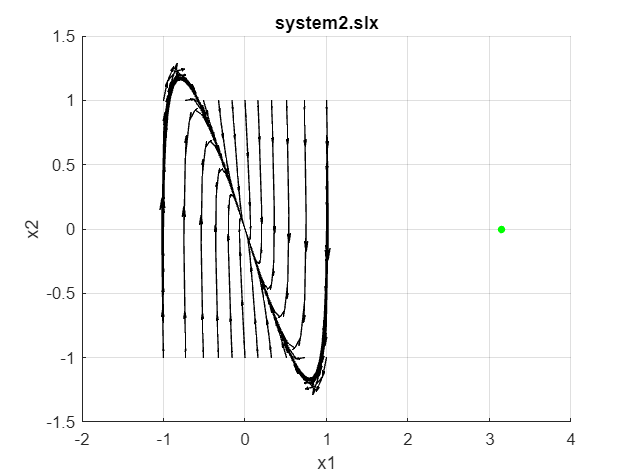


fig = draw_phase("system2.slx");
hold on;
plot(bal_point(:, 1), bal_point(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
hold off;

bal_point =      0     0


A =          0    1.0000
  -19.6200  -12.0000


point_eigs =   -10.0472
   -1.9528


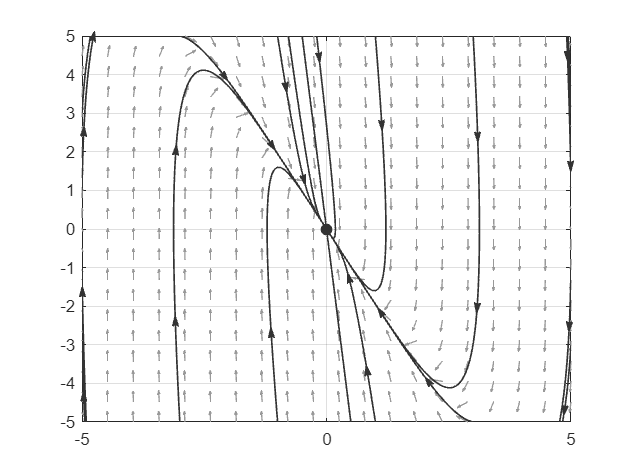

bal_point =     3.1416         0


A =          0    1.0000
   19.6200  -12.0000


point_eigs =   -13.4579
    1.4579


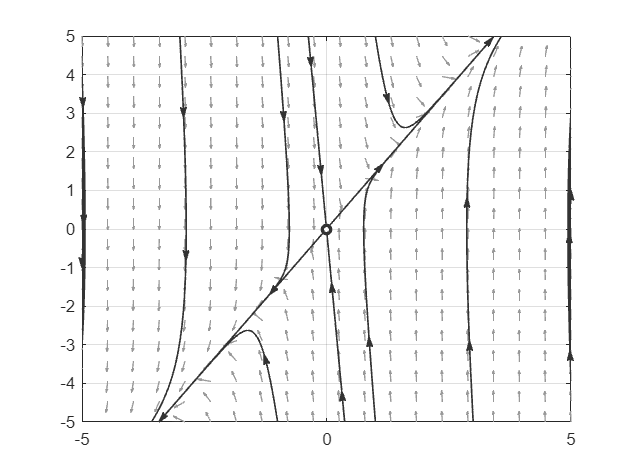

%saveas(fig ,"wykresy/2system2.jpg");

for i = 1 : size(Am,3)
    bal_point = bal_points(i,:)
    A = Am(:,:,i)
    point_eigs = all_eigs(:,i)
    plot_pp_by_A(A)
end

a = 1;

syms y1 y2 real
% Prawe strony rownan stanu
eqns = [y2 - y1^3 - a * y1; -y1];
[eigs, A, bal_point] = lapunov_stab_two_eqns(eqns)

eigs =   -0.5000 - 0.8660i
  -0.5000 + 0.8660i


A =     -1     1
    -1     0


bal_point =      0     0


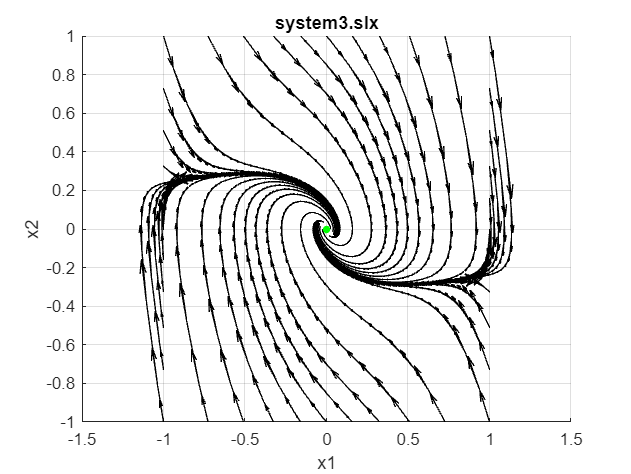


fig = draw_phase("system3.slx");
%saveas(fig ,"wykresy/system3.jpg");
hold on;
plot(bal_point(:, 1), bal_point(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
hold off;

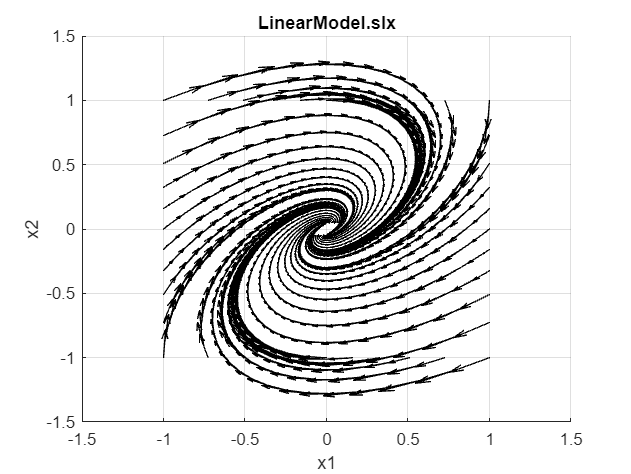


fig = draw_phase("LinearModel.slx");

%saveas(fig ,"wykresy/lin_system3.jpg");

a = 2;

syms y1 y2 real
% Prawe strony rownan stanu
eqns = [y2 - y1^3 - a * y1; -y1];
[eigs, A, bal_point] = lapunov_stab_two_eqns(eqns)

eigs =     -1
    -1


A =     -2     1
    -1     0


bal_point =      0     0


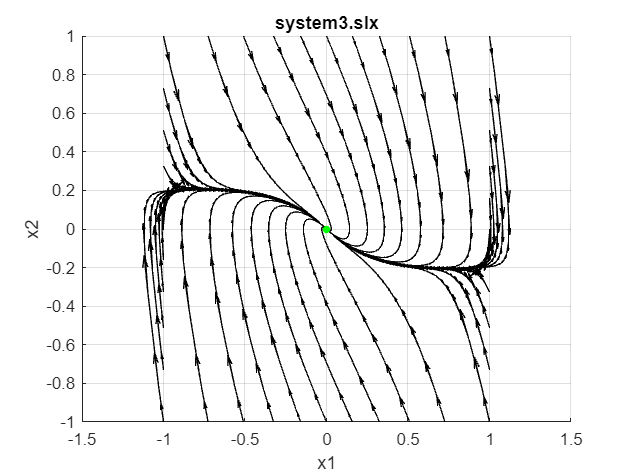


fig = draw_phase("system3.slx");
%saveas(fig ,"wykresy/2system3.jpg");
hold on;
plot(bal_point(:, 1), bal_point(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
hold off;

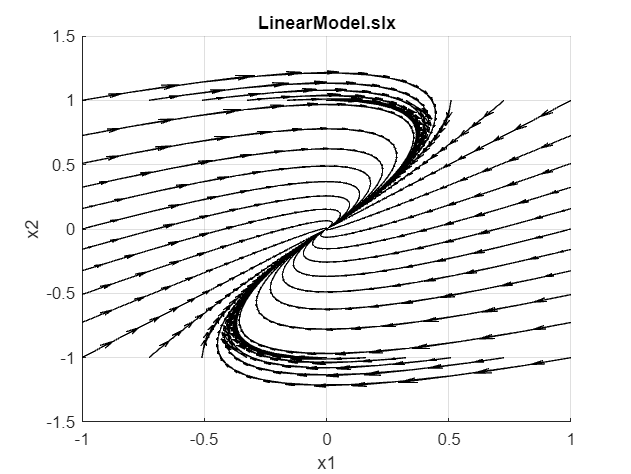


fig = draw_phase("LinearModel.slx");

%saveas(fig ,"wykresy/2lin_system3.jpg");

function [fig] = draw_phase(model_name)
    global x0
    T=6;
    fig = figure; hold on; grid on;
    a = 0 : pi/20 : 2*pi; X1 = [cos(a); sin(a)];
    X2 = X1 ./ [max(abs(X1)); max(abs(X1))];
    M = size(X2, 2);
    
    for i = 1:M
        x0 = X2(:, i);
        puste = sim(model_name, T);
        y1 = puste.y.signals(1).values;
        y2 = puste.y.signals(2).values;
        % Strzałki na portrecie fazowym
        quiver(y1, y2, gradient(y1), gradient(y2), "k");
        % Portret fazowy
        plot(y1, y2, 'k-');
        title(model_name);
        xlabel('x1'); ylabel('x2');
    end

    hold off;
end

function [eigs, A, bal_points] = lapunov_stab(eqn)
    % Rozbicie na uklad rownan pierwszego rzedu
    V = odeToVectorField(eqn)
    V = matlabFunction(V,'vars',{'t','Y'})
    figure;
    plotpp(V);
    syms t y1 y2 real
    V = V(t, [y1 y2]);
    % Punkty rownowagi
    bal_points = solve(V == 0);
    bal_points = double([bal_points.y1, bal_points.y2]);
    % Zaznaczenie punktow na wykresie
    hold on;
    plot(bal_points(:, 1), bal_points(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
    hold off;
    % Jakobian punktow rownowagi
    J(y1, y2) = jacobian(V);
    A = zeros(2, 2, size(bal_points, 1));
    for i = 1 : size(bal_points, 1)
        point_J = J(bal_points(i, 1), bal_points(i, 2));
        % wartosci wlasne
        eigvals = eig(point_J);
        eigs(:,i) = double(eigvals);
        % Macierz A ukladu zlinearyzowanego
        A(:,:,i) = double(point_J);
    end
end

function [eigs, A, bal_points] = lapunov_stab2(eqn)
    % Rozbicie na uklad rownan pierwszego rzedu
    V = odeToVectorField(eqn)
    V = matlabFunction(V,'vars',{'t','Y'});
    figure;
    plotpp(V);
    syms t y1 y2 real
    V = V(t, [y1 y2]);
    % Punkty rownowagi
    bal_y2 = 0;  % Podstawienie y1' = y2
    [bal_y1, param, cond] = solve(subs(V(2),y2,bal_y2) == 0, y1, 'ReturnConditions', true)
    assume(cond);
    sol_param = solve(0<=bal_y1, bal_y1<2*pi, param);
    bal_y1 = unique(subs(bal_y1, sol_param));
    bal_points = double([bal_y1, ones(length(bal_y1),1) * bal_y2]);
    eigs = zeros(2, size(bal_points,1));
    % Zaznaczenie punktow na wykresie
    hold on;
    plot(bal_points(:,1), bal_points(:,2), 'go', "MarkerFaceColor","g", "MarkerSize", 4);
    hold off;
    % Jakobiany punktow rownowagi
    J(y1, y2) = jacobian(V);
    A = zeros(2, 2, size(bal_points, 1));
    for i = 1 : size(bal_points, 1)
        point_J = J(bal_points(i, 1), bal_points(i, 2));
        % wartosci wlasne
        eigvals = eig(point_J);
        eigs(:,i) = eigvals;
        % Macierz A ukladu zlinearyzowanego
        A(:,:,i) = double(point_J);
    end
end

function [eigs, A, bal_points] = lapunov_stab_two_eqns(eqns)
    % Punkty rownowagi
    bal_points = solve(eqns);
    bal_points = double([bal_points.y1, bal_points.y2]);
    eigs = zeros(2, size(bal_points,1));
    % Jakobiany punktow rownowagi
    syms y1 y2 real
    J(y1, y2) = jacobian(eqns);
    A = zeros(2, 2, size(bal_points, 1));
    for i = 1 : size(bal_points, 1)
        point_J = J(bal_points(i, 1), bal_points(i, 2));
        % wartosci wlasne
        eigvals = eig(point_J);
        eigs(:,i) = eigvals;
        % Macierz A ukladu zlinearyzowanego
        A(:,:,i) = double(point_J);
    end
end

function [] = plot_pp_by_A(A)
    V = @(t, Y) A * [Y(1); Y(2)];
    figure;
    plotpp(V);
end